# load the data

load JR_2015-12-04_truncated2.mat

## plot all the trials

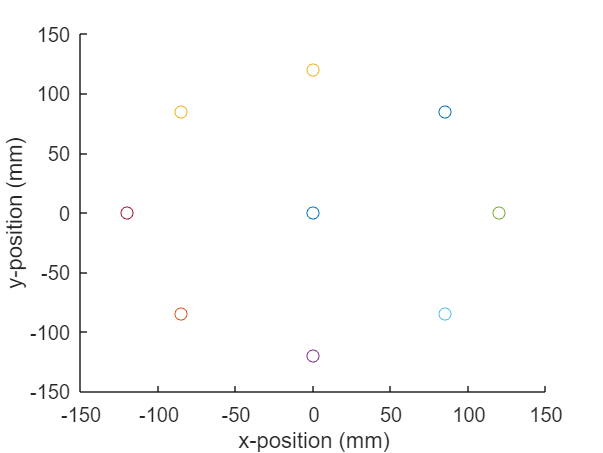

figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');

for i = 1:numel(R)
    plot(R(i).target(1), R(i).target(2), 'marker', 'o');
end


% print -dpdf targets.pdf

success_array = [];

for i = 1:numel(R)
    success_array = [success_array R(i).isSuccessful];
end

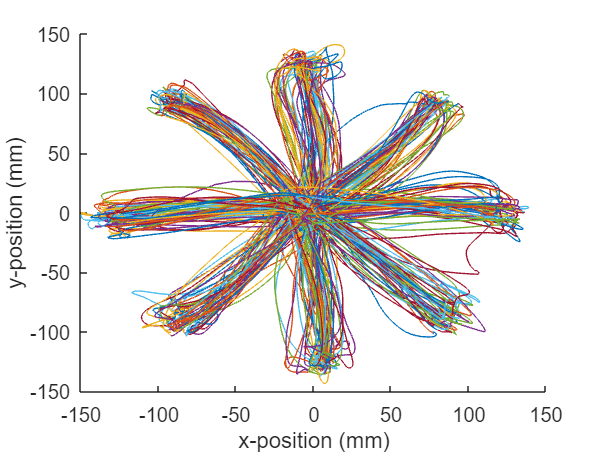

figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');

for i = 1:numel(R)
    plot(R(i).cursorPos(1,:), R(i).cursorPos(2,:));
end

xlim([-150, 150]);
ylim([-150, 150]);


% print -dpdf cursorpos.pdf

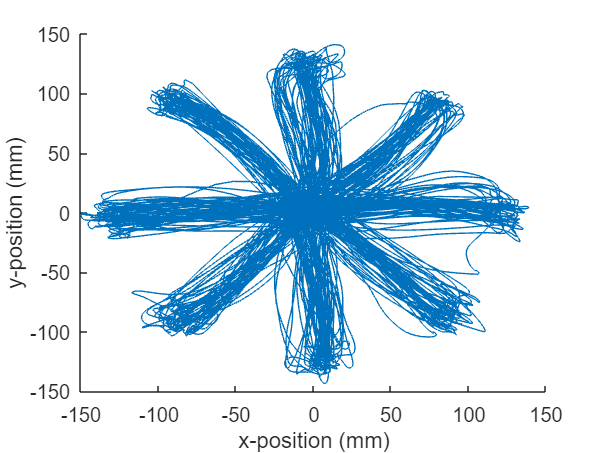

figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');

X = [R.cursorPos];

plot(X(1,:), X(2,:));

xlim([-150, 150]);
ylim([-150, 150]);


% print -dpdf cursorpos2.pdf

figure;

imagesc([R(1).spikeRaster; R(1).spikeRaster2]);
xlabel('Time [ms]');
ylabel('Neuron number');

% print -dpdf spikeraster.pdf

Rtrain = R(1:400);
Rtest = R(401:506);

dt = 25; % in units of ms
Y = [Rtrain.spikeRaster; Rtrain.spikeRaster2];
Y_bin = bin(Y, dt, 'sum');

         192      411626

         192       16465



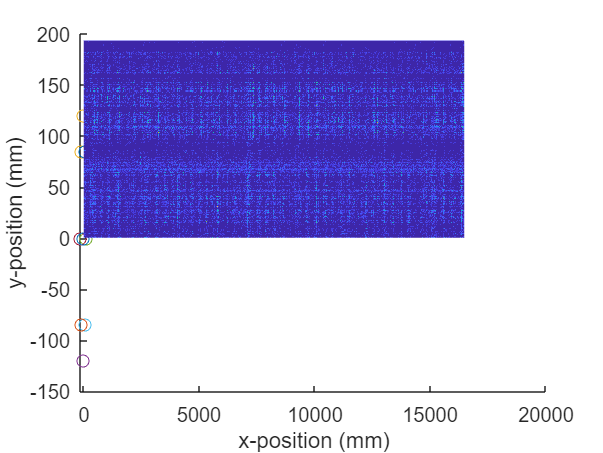

Y_bin = [Y_bin; ones(1, size(Y_bin, 2))];
imagesc(Y_bin);

dt = 25;
X = [Rtrain.cursorPos];
disp(size(X))

           3      411626



X_bin = bin(X, dt, 'first');
X_bin = (X_bin(1:2, 2:end) - X_bin(1:2, 1:end-1)) / dt;

% this line below builds the decoder
L = X_bin * pinv(Y_bin);

L2 = X_bin * Y_bin' * inv(Y_bin*Y_bin');

% now, let's see how it does on testing data.
dt = 25;
decoded_positions = {};

for i = 1:numel(Rtest)
    
    % Get the new neural data we're going to decode.
    Ytest = [Rtest(i).spikeRaster; Rtest(i).spikeRaster2]; % extract test data
    Ytest = bin(Ytest, dt, 'sum'); % bin the data
    Ytest = [Ytest; ones(1, size(Ytest, 2))]; % append 1's for the bias term
    
    % Decode the data.
    Xtest = L * Ytest; % 2 x T
    decodedPos = [Rtest(i).cursorPos(1:2, 1)]; % the trajectory starts at the same point; then we'll integrate velocities from this starting point.
    % Integrate the decoded velocities.
    for j = 1:size(Xtest, 2) % for j = 1 to time T
        decodedPos = [decodedPos decodedPos(:, end) + dt * Xtest(:, j)];
    end
    disp(size(decodedPos))
    
    % store decoded positions plotting later.
    decoded_positions = {decoded_positions{:}, decodedPos};
    
end

     2    39

     2    49

     2    37

     2    41

     2    37

     2    42

     2    38

     2    41

     2    35

     2    43

     2    39

     2    43

     2    36

     2    47

     2    36

     2    45

     2    37

     2    41

     2    41

     2    44

     2    40

     2    43

     2    38

     2    50

     2    41

     2    41

     2    41

     2    80

     2    40

     2    43

     2    37

     2    42

     2    39

     2    51

     2    36

     2    44

     2    35

     2    43

     2    45

     2    45

     2    40

     2    43

     2    43

     2    49

     2    34

     2    41

     2    35

     2    43

     2    37

     2    44

     2    37

     2    45

     2    39

     2    47

     2    40

     2    51

     2    42

     2    43

     2    38

     2    41

     2    38

     2    47

     2    37

     2    43

     2    37

     2    47

     2    35

     2    41

     2    40

     2    42

     2    38

     2

## plot the decoded positions.

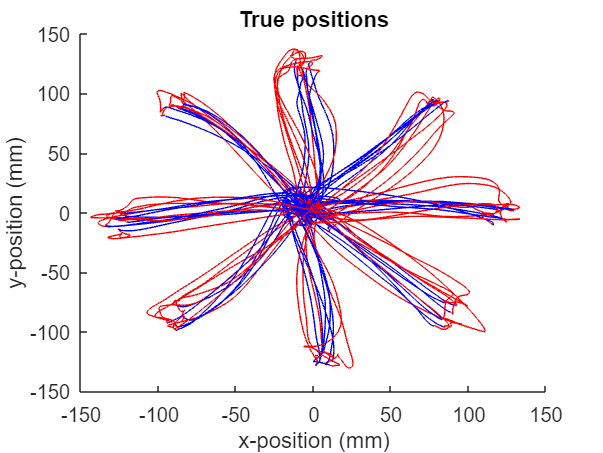

hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


     0



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


     0



hi


     0



hi


     0



hi


     0



hi


     0



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


   84.8500



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


     0



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


     0



hi


     0



hi


   84.8500



hi


     0



hi


   120



hi


     0



hi


     0



% plot the true trajectories
% we'll color center-out reaches in red; center-back reaches in blue.
figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');
title('True positions');
for i = 1:length(Rtest)
    is_center_back = abs(R(i).target(1)) + abs(R(i).target(2)) == 0;
    disp('hi')
    disp(abs(R(i).target(1)))
    if is_center_back
        plotcolor = 'b';
    else
        plotcolor = 'r';
    end
    plot(Rtest(i).cursorPos(1,:), Rtest(i).cursorPos(2,:), plotcolor);
end

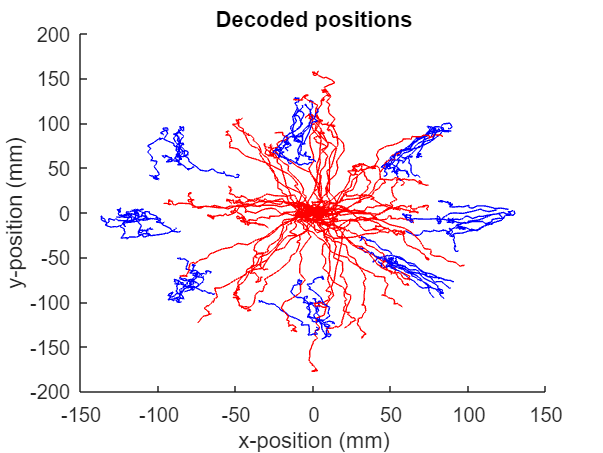


% print -dpdf true_test_pos.pdf

% plot the decoded trajectories
figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');
title('Decoded positions');

for i = 1:length(decoded_positions)
    is_center_out = abs(R(i).target(1)) + abs(R(i).target(2)) == 0;
    if is_center_out
        plotcolor = 'b';
    else
        plotcolor = 'r';
    end
    plot(decoded_positions{i}(1,:), decoded_positions{i}(2,:), plotcolor);
end


% print -dpdf dec_test_pos.pdf

## calculate mean-square error

dt = 25;
mean_square_errors = [];
for i = 1:length(Rtest)
    true_traj = bin(Rtest(i).cursorPos(1:2,:), dt, 'first');
    decoded_traj = decoded_positions{i};
    
    % we may have decoded an extra dt relative to the true
    % trajectory, so we need to truncate to be sure.
    decoded_traj = decoded_traj(:, 1:size(true_traj, 2));
    
    mean_square_errors = [mean_square_errors mean(sum((true_traj - decoded_traj).^2, 1))];
end

mean_square_error = mean(mean_square_errors)

## project part 1

Y_bin_smooth = zeros(size(Y_bin));

for i = 1:size(Y_bin, 1) - 1
    Y_bin_smooth(i,:) = conv(Y_bin(i,:), [1 1 1 1 1 1 1], 'same');
end

this line below builds the decoder

L = X_bin * pinv(Y_bin_smooth);

% now, let's see how it does on testing data.
dt = 25;
decoded_positions = {};

for i = 1:numel(Rtest)
    
    % Get the new neural data we're going to decode.
    Ytest = [Rtest(i).spikeRaster; Rtest(i).spikeRaster2]; % extract test data
    Ytest = bin(Ytest, dt, 'sum'); % bin the data
    
    for j = 1:size(Ytest, 1)
        Ytest(j,:) = conv(Ytest(j,:), [1 1 1 1 1 1 1], 'same');
    end
    
    Ytest = [Ytest; ones(1, size(Ytest, 2))]; % append 1's for the bias term
    
    % Decode the data.
    Xtest = L * Ytest;
    decodedPos = [Rtest(i).cursorPos(1:2, 1)]; % the trajectory starts at the same point; then we'll integrate velocities from this starting point.
    
    % Integrate the decoded velocities.
    for j = 1:size(Xtest, 2)
        decodedPos = [decodedPos decodedPos(:, end) + dt * Xtest(:, j)];
    end
    
    % store decoded positions plotting later.
    decoded_positions = {decoded_positions{:}, decodedPos};
    
end

## plot the decoded positions.

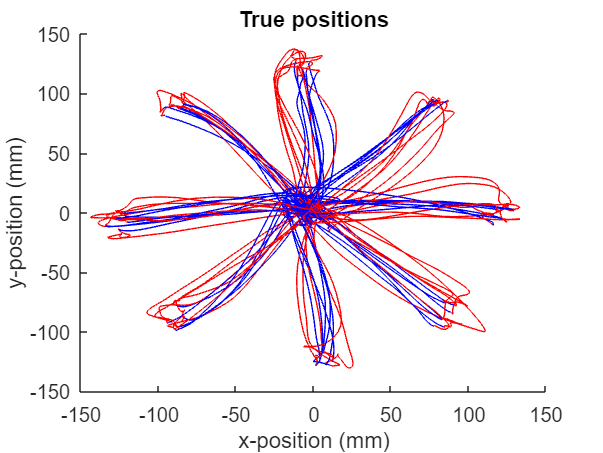

     0

  -84.8500

     0

  -120

     0

     0

     0

  -84.8500

     0

   84.8500

     0

   84.8500

     0

   120

     0

     0

     0

     0

     0

   120

     0

  -84.8500

     0

   84.8500

     0

  -84.8500

     0

  -120

     0

   84.8500

     0

   84.8500

     0

     0

     0

  -84.8500

     0

   120

     0

  -120

     0

  -84.8500

     0

     0

     0

   84.8500

     0

   84.8500

     0

  -84.8500

     0

   120

     0

  -84.8500

     0

  -120

     0

     0

     0

     0

     0

   84.8500

     0

  -120

     0

     0

     0

     0

     0

  -84.8500

     0

   84.8500

     0

  -84.8500

     0

   84.8500

     0

   120

     0

     0

     0

   84.8500

     0

   120

     0

  -84.8500

     0

   84.8500

     0

  -120

     0

     0

     0

  -84.8500

     0

   84.8500

     0

   84.8500

     0

     0

     0

   120

     0

  -120

     0

  -84.8500



% plot the true trajectories
% we'll color center-out reaches in red; center-back reaches in blue.
figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');
title('True positions');

for i = 1:length(Rtest)
    is_center_back = abs(Rtest(i).target(1)) + abs(Rtest(i).target(2)) == 0;
    disp(Rtest(i).target(1))
    if is_center_back
        plotcolor = 'b';
    else
        plotcolor = 'r';
    end
    plot(Rtest(i).cursorPos(1,:), Rtest(i).cursorPos(2,:), plotcolor);
end

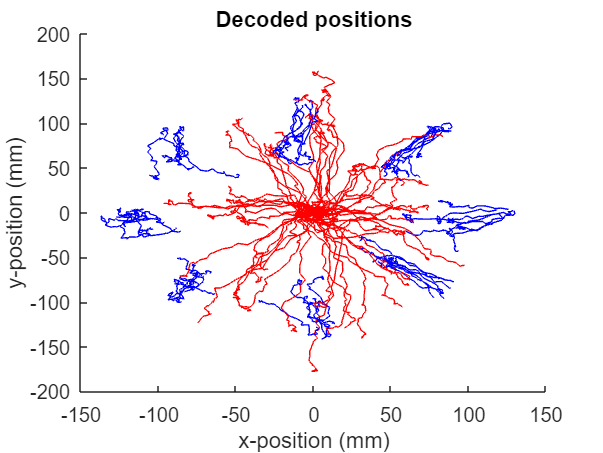


% print -dpdf true_test_pos.pdf

% plot the decoded trajectories
figure;
hold all;
xlabel('x-position (mm)');
ylabel('y-position (mm)');
title('Decoded positions');

for i = 1:length(decoded_positions)
    is_center_out = abs(R(i).target(1)) + abs(R(i).target(2)) == 0;
    if is_center_out
        plotcolor = 'b';
    else
        plotcolor = 'r';
    end
    plot(decoded_positions{i}(1,:), decoded_positions{i}(2,:), plotcolor);
end


% print -dpdf dec_test_pos.pdf

## calculate mean-square error

dt = 25;
mean_square_errors = [];
for i = 1:length(Rtest)
    true_traj = bin(Rtest(i).cursorPos(1:2,:), dt, 'first');
    decoded_traj = decoded_positions{i};

    % we may have decoded an extra dt relative to the true
    % trajectory, so we need to truncate to be sure.
    decoded_traj = decoded_traj(:, 1:size(true_traj, 2));
    mean_square_errors = [mean_square_errors mean(sum((true_traj - decoded_traj).^2, 1))];
end

mean_square_error = mean(mean_square_errors)

mean_square_error = 3.4926e+03